# MAIN SCRIPT

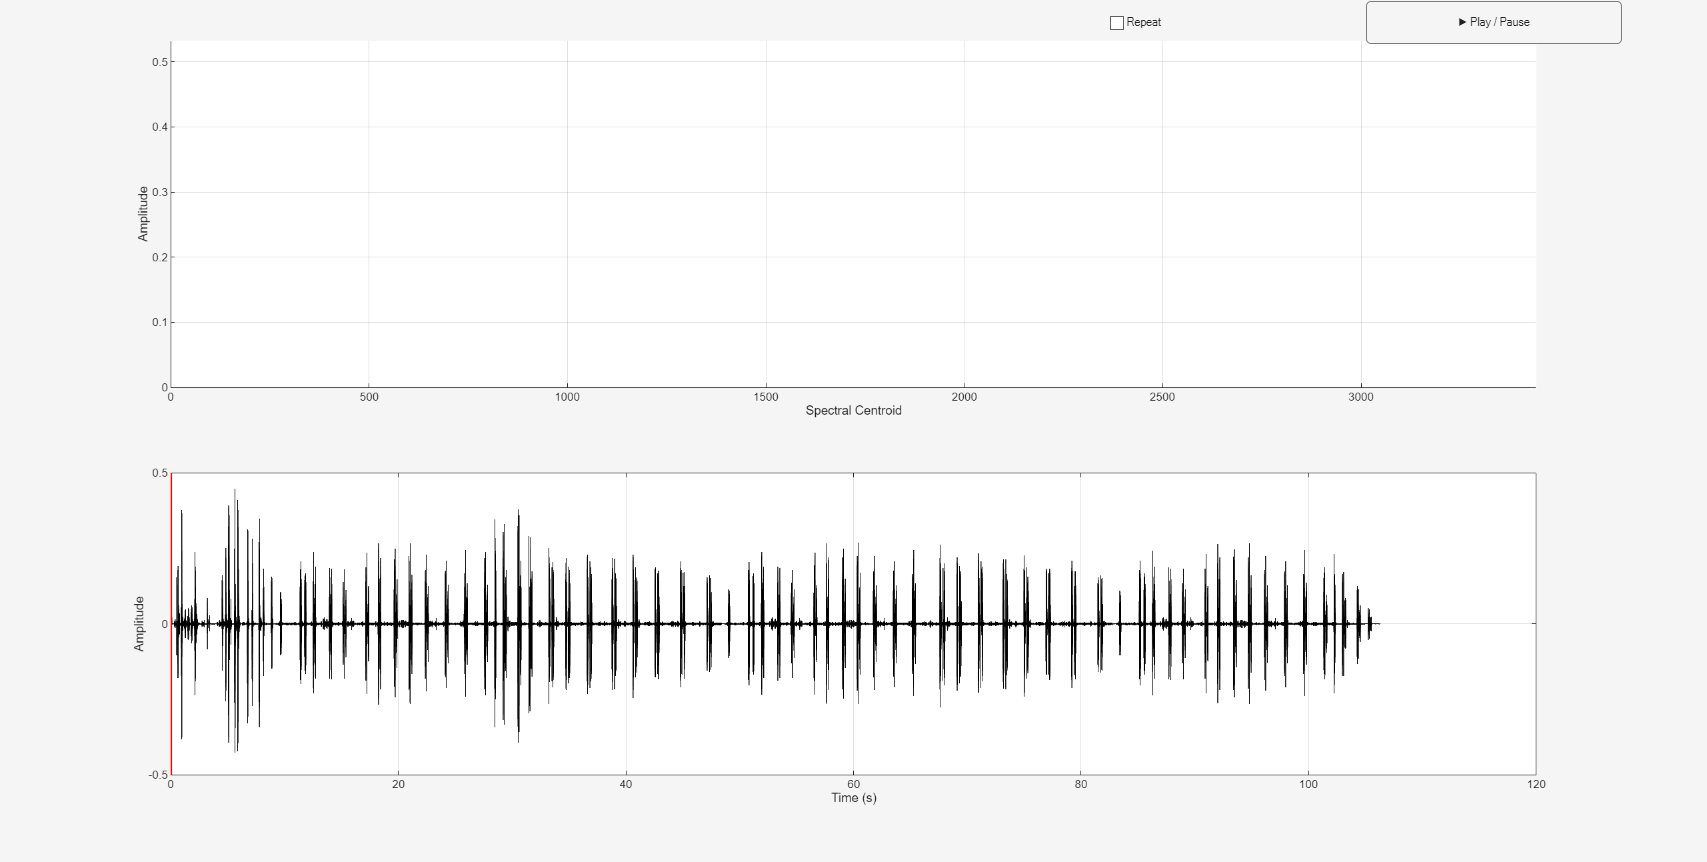

clear; clc; close all;

audioFile = 'audio.wav';  % Your audio file path

% Step 1: Read and denoise
[x, fs] = audio_read_denoise(audioFile);

% Step 2: Extract features
[feats, centroids, amps, lifetimes, absTimes, segs] = feature_extraction(x, fs);

% Step 3: Animated playback and visualization
animated_feature_playback(x, fs, feats, centroids, amps, lifetimes, absTimes);

## Read audio and lightly denoise

function [x, fs] = audio_read_denoise(audio)
    [x, fs] = audioread(audio);
    if size(x,2) > 1
        x = mean(x,2); % Stereo -> Mono
    end
    x = sgolayfilt(x, 3, 11); % Light smoothing
end

## Feature extraction

function [feats, centroids, amps, lifetimes, absTimes, segs] = feature_extraction(x, fs)
    % Smooth envelope
    env = smoothdata(abs(hilbert(x)), 'gaussian', round(0.02*fs));
    thr = mean(env) + 0.5*std(env);
    segs = findSegments(env, thr, fs);

    if isempty(segs)
        error('No syllables detected. Try adjusting the threshold.');
    end

    nSeg = size(segs,1); nMFCC = 13;
    feats = zeros(nSeg,nMFCC); centroids = zeros(nSeg,1); amps = zeros(nSeg,1);
    lifetimes = zeros(nSeg,1); absTimes = zeros(nSeg,1);

    for i=1:nSeg
        seg = x(segs(i,1):segs(i,2));
        coeffs = cepstralFeatures(seg, fs, nMFCC);
        feats(i,:) = mean(coeffs,1);
        centroids(i) = mean(spectralCentroid(seg, fs));
        amps(i) = rms(seg)/max(env);
        lifetimes(i) = length(seg)/fs;
        absTimes(i) = segs(i,1)/fs;
    end
end

## Helper: segment detection

function segments = findSegments(env, thr, fs)
    above = env > thr;
    edges = diff([0; above; 0]);
    starts = find(edges==1); ends = find(edges==-1)-1;
    segs = [starts ends];
    minDur = 0.03*fs; maxDur = 1.0*fs;
    durs = segs(:,2) - segs(:,1);
    segments = segs(durs > minDur & durs < maxDur, :);
end 

## Helper: cepstral features

function c = cepstralFeatures(x, fs, nCoeffs)
    if isempty(x)
        c = zeros(1,nCoeffs); return;
    end
    winLength = round(0.025*fs);
    win = hamming(winLength,'periodic');
    [S,~] = melSpectrogram(x, fs, ...
        'Window', win, ...
        'OverlapLength', round(0.015*fs), ...
        'NumBands', 26, ...
        'FFTLength', 2^nextpow2(winLength), ...
        'FilterBankNormalization', 'bandwidth', ...
        'SpectrumType', 'power', ...
        'ApplyLog', false);
    logMel = log(S+eps);
    c = dct(logMel);
    c = c(1:nCoeffs,:).';
end

## Animated playback with 3D scatter

function animated_feature_playback(x, fs, feats, centroids, amps, lifetimes, absTimes)
    fig = figure('Name','Audio Feature Playback','NumberTitle','off');

    % --- Precompute ranges for 3D scatter (fixed axes) ---
    xLim = [0 max(centroids)*1.1];
    yLim = [0 max(amps)*1.1];
    zLim = [0 max(lifetimes)*1.1];

    % 3D scatter axes
    ax3D = axes('Position',[0.1 0.55 0.8 0.4]);
    xlabel('Spectral Centroid'); ylabel('Amplitude'); zlabel('Duration');
    grid on; rotate3d on; hold on;
    xlim(ax3D, xLim); ylim(ax3D, yLim); zlim(ax3D, zLim);

    % Scatter for cumulative points
    hActive = scatter3(NaN, NaN, NaN, 100, 'r', 'filled');

    % Line connecting the last two points (consecutive)
    hLineConsec = plot3(NaN, NaN, NaN, 'g', 'LineWidth', 2);

    % Line connecting from origin to current point
    hLineOrigin = plot3(NaN, NaN, NaN, 'b', 'LineWidth', 2);

    % Waveform axes
    axWave = axes('Position',[0.1 0.1 0.8 0.35]);
    t = (0:length(x)-1)/fs;
    plot(axWave, t, x, 'k'); hold on;
    playCursor = plot(axWave, [0 0], ylim, 'r','LineWidth',2);
    xlabel(axWave,'Time (s)'); ylabel(axWave,'Amplitude'); grid(axWave,'on');

    % Audio player
    player = audioplayer(x, fs);
    isPlaying = false;

    % Control buttons
    uicontrol('Style','pushbutton','String','▶ Play / Pause','Units','normalized', ...
        'Position',[0.8 0.95 0.15 0.05],'Callback',@togglePlayPause);

    repeatMode = false;
    uicontrol('Style','checkbox','String','Repeat','Units','normalized', ...
        'Position',[0.65 0.95 0.1 0.05],'Callback',@(src,~) setRepeat(src));

    % Store points that have appeared so far (cumulative)
    appeared = [];

    % Update repeat checkbox
    function setRepeat(src)
        repeatMode = src.Value;
    end

    % Play/pause toggle
    function togglePlayPause(~,~)
        if ~isPlaying
            isPlaying = true;
            play(player);
            animate();
        else
            pause(player);
            isPlaying = false;
        end
    end

    % Animation loop
    function animate()
        while isPlaying
            curSample = player.CurrentSample;
            if curSample > length(x)
                if repeatMode
                    stop(player);
                    play(player);
                    curSample = 1;
                    appeared = [];
                else
                    isPlaying = false;
                    break;
                end
            end

            % Update waveform cursor
            set(playCursor, 'XData', [t(curSample) t(curSample)]);

            % Find syllables that have started
            idx = find(absTimes <= t(curSample) & t(curSample) <= (absTimes + lifetimes));
            newPoints = setdiff(idx, appeared); % newly active points
            appeared = unique([appeared; idx]);

            % Update scatter points (cumulative)
            if ~isempty(appeared)
                set(hActive, 'XData', centroids(appeared), ...
                             'YData', amps(appeared), ...
                             'ZData', lifetimes(appeared));

                % Origin-to-point connection (show a bit longer)
                if ~isempty(newPoints)
                    lastPoint = newPoints(end);
                    set(hLineOrigin, 'XData', [0 centroids(lastPoint)], ...
                                     'YData', [0 amps(lastPoint)], ...
                                     'ZData', [0 lifetimes(lastPoint)]);
                    drawnow limitrate
                    pause(0.15);  % visible for ~150ms
                end

                % Consecutive points connection
                if length(appeared) >= 2
                    lastTwo = appeared(end-1:end);
                    set(hLineConsec, 'XData', centroids(lastTwo), ...
                                     'YData', amps(lastTwo), ...
                                     'ZData', lifetimes(lastTwo));
                end
            end

            drawnow limitrate
            % Clear origin-to-point line after pause
            set(hLineOrigin, 'XData', NaN, 'YData', NaN, 'ZData', NaN);
        end
    end
end